## Import fatigue data

clear all
data = readtable("G20CrNi2Mo Bearing Steel Data_Zhao.xlsx");

%data.Properties.VariableNames
%unique(data.ContactStressAmplitude_MPa_);
%groupcounts(data, "ContactStressAmplitude_MPa_");

## Parameter estimation using MLE

A custom function can be defined to be able to conduct mle for 3P Weibull. There can be issues faced with this approach, specifically when the shape parameter is less than unity. This is indeed the case for the bearing steel. When this is the case, the pdf approaches infinity near the location parameter. 

% a = scale parameter
% b = shape parameter
% c = location parameter
% See matlab documentation on this distribution (and parameter naming
% convention) at https://www.mathworks.com/help/releases/R2025b/stats/three-parameter-weibull-distribution.html

stress_levels = unique(data.ContactStressAmplitude_MPa_);
num_stress_levels = numel(stress_levels);

% Arrays to store parameter estimates
a_estimates_MLE = zeros(num_stress_levels,1);
b_estimates_MLE = zeros(num_stress_levels,1);
c_estimates_MLE = zeros(num_stress_levels,1);
B1_lives_3PW_MLE = zeros(num_stress_levels,1);

% custom 3P Weibull pdf 
custompdf = @(x,a,b,c) wblpdf(x-c,a,b);

% options for iterative estimation
options = statset('mlecustom');
options.FunValCheck = 'off';
options.MaxIter = 10000;
options.MaxFunEvals = 10000;
options.Display = 'final';

for i = 1:num_stress_levels
    current_stress = stress_levels(i);
    life_i = data.NumberOfCycles( ...
        data.ContactStressAmplitude_MPa_ == current_stress);
    life_i = life_i(:);

    %initial estimates
    c0 = 0.5 * min(life_i);
    shifted_life = life_i - c0;

    b0 = 1.0;
    a0 = mean(shifted_life) / gamma(1 + 1/b0);

    start_values = [a0, b0, c0];

    % Keep the location parameter strictly below the smallest observation
    lower_bounds = [eps, eps, -Inf];
    upper_bounds = [Inf, Inf, min(life_i) * (1 - 1e-8)];

    % mle 
    params = mle(life_i, ...
        'pdf', custompdf, ...
        'Start', start_values, ...
        'LowerBound', lower_bounds, ...
        'UpperBound', upper_bounds, ...
        'Options', options);

    % store parameter estimates
    a_estimates_MLE(i) = params(1);
    b_estimates_MLE(i) = params(2);
    c_estimates_MLE(i) = params(3);

    % calculate the B1 life 
    B1_lives_3PW_MLE(i) = c_estimates_MLE(i) + a_estimates_MLE(i) * (-log(0.99))^(1 / b_estimates_MLE(i));
end

 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-06 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-06 

 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-06 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-06 

 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-06 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-06 

 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-06 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-06 



%% Check location estimates against minimum observations

min_life = zeros(num_stress_levels,1);
location_gap = zeros(num_stress_levels,1);

for i = 1:num_stress_levels
    life_i = data.NumberOfCycles( ...
        data.ContactStressAmplitude_MPa_ == stress_levels(i));

    min_life(i) = min(life_i);
    location_gap(i) = min_life(i) - c_estimates_MLE(i);
end

location_check = table( ...
    stress_levels, min_life, c_estimates_MLE, location_gap);

location_check

location_check = 4×4 table
    stress_levels    min_life    c_estimates_MLE    location_gap
    _____________    ________    _______________    ____________

        4900         2.25e+07       2.25e+07            0.225   
        5500         8.77e+06       8.77e+06           0.0877   
        6100         5.88e+06       5.88e+06           0.0588   
        6700         1.63e+06       1.63e+06           0.0163   


% stoore and display MLE results
MLE_results_3PW = table(stress_levels, a_estimates_MLE, b_estimates_MLE, c_estimates_MLE, B1_lives_3PW_MLE)

MLE_results_3PW = 4×5 table
    stress_levels    a_estimates_MLE    b_estimates_MLE    c_estimates_MLE    B1_lives_3PW_MLE
    _____________    _______________    _______________    _______________    ________________

        4900           5.1618e+08           0.52331           2.25e+07           2.2579e+07   
        5500            2.199e+08           0.54371           8.77e+06           8.8165e+06   
        6100           4.3606e+07           0.52026           5.88e+06           5.8863e+06   
        6700            2.753e+07           0.42829           1.63e+06           1.6306e+06   


## PPLR 

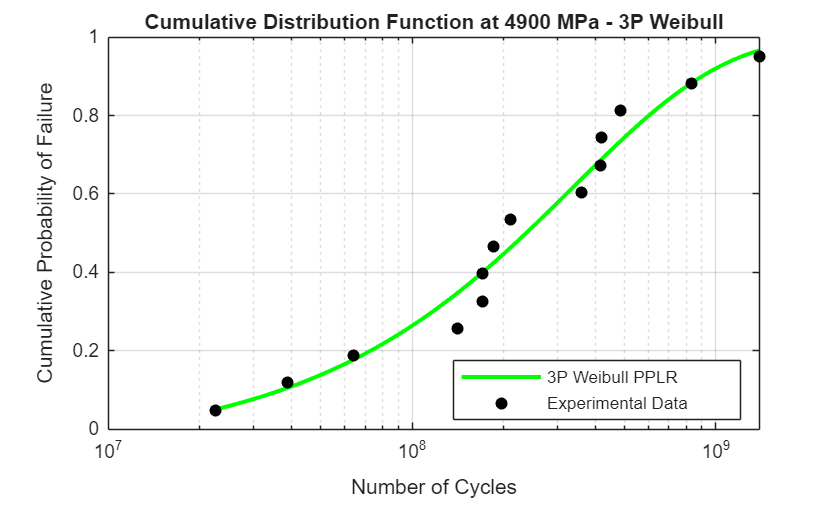

%% 2.2 PPLR - Three-parameter Weibull

% a = scale parameter
% b = shape parameter
% c = location parameter

stress_levels = unique(data.ContactStressAmplitude_MPa_);
num_stress_levels = numel(stress_levels);

% Arrays to store parameter estimates
a_estimates = zeros(num_stress_levels,1);
b_estimates = zeros(num_stress_levels,1);
c_estimates = zeros(num_stress_levels,1);
B1_lives_3PW_PPLR = zeros(num_stress_levels,1);
max_r_array = zeros(num_stress_levels,1);

% Cell arrays to store plotting data
cdf_x = cell(num_stress_levels,1);
cdf_3PW_PPLR = cell(num_stress_levels,1);
cdf_life_sorted = cell(num_stress_levels,1);
cdf_empirical_F = cell(num_stress_levels,1);

probability_X = cell(num_stress_levels,1);
probability_Y = cell(num_stress_levels,1);
probability_Y_fit = cell(num_stress_levels,1);

% 3P Weibull CDF
weib3_cdf = @(x,a,b,c) (x > c) .* (1 - exp(-((x - c) ./ a).^b));

% tail fit check storage 
tail_fit_lives_3PW = cell(num_stress_levels,1);
tail_fit_F_empirical_3PW = cell(num_stress_levels,1);
tail_fit_dF_3PW = cell(num_stress_levels,1);
tail_fit_abs_dF_3PW = cell(num_stress_levels,1);

for j = 1:num_stress_levels
    current_stress = stress_levels(j);
    life_j = data.NumberOfCycles(data.ContactStressAmplitude_MPa_ == current_stress);
    life_j_sorted = sort(life_j(:));
    num_observations_j = numel(life_j_sorted);
    observation_ranks = (1:num_observations_j)';

    % Median rank plotting positions
    % F_i = (i - 0.3)/(n + 0.4)
    F_j = (observation_ranks - 0.3) ./ ...
        (num_observations_j + 0.4);
    Y_j = log(-log(1 - F_j));

    % Search for the location parameter c
    max_r_j = -Inf;
    best_c = NaN;
    X_max_j = [];

    c_range_j = linspace(0, 0.999 * min(life_j_sorted), 100000);

    for k = 1:numel(c_range_j)
        X_k = log(life_j_sorted - c_range_j(k));
        r_2PW_matrix = corrcoef(X_k, Y_j); % calculates correlation coefficient matrix
        r_2PW = r_2PW_matrix(1,2);
        %r_2PW = r_2PW ^ 2;

        if isfinite(r_2PW) && r_2PW > max_r_j
            max_r_j = r_2PW;
            best_c = c_range_j(k);
            X_max_j = X_k;
        end
    end

    % Check that a usable location estimate was found
    if isnan(best_c)
        error('No valid location estimate found at %g MPa.', current_stress);
    end

    % Linear regression for the three-parameter Weibull
    fitted_line = polyfit(X_max_j, Y_j, 1);
    reg_slope = fitted_line(1);
    reg_intercept = fitted_line(2);

    if reg_slope <= 0
        error('Non-positive Weibull shape estimate at %g MPa.', current_stress);
    end

    c_estimates(j) = best_c;
    b_estimates(j) = reg_slope;
    a_estimates(j) = exp(-reg_intercept / b_estimates(j));

    % Calculate B1 life
    B1_lives_3PW_PPLR(j) = c_estimates(j) + a_estimates(j) * (-log(0.99))^(1 / b_estimates(j));

    max_r_array(j) = max_r_j;

    % Calculate fitted CDF
    life_j_lin = logspace(log10(min(life_j_sorted)), log10(max(life_j_sorted)), 200);

    cdf_3PW = weib3_cdf(life_j_lin, a_estimates(j), b_estimates(j), c_estimates(j));

    % Store data for combined plotting later
    cdf_x{j} = life_j_lin;
    cdf_3PW_PPLR{j} = cdf_3PW;
    cdf_life_sorted{j} = life_j_sorted;
    cdf_empirical_F{j} = F_j;

    % Tail-fit check at the 3 lowest observed fatigue lives
    N_tail = life_j_sorted(1:3);
    F_empirical_tail = F_j(1:3);
    F_predicted_tail = weib3_cdf(N_tail, a_estimates(j), b_estimates(j), c_estimates(j));

    % Signed and absolute CDF differences
    dF_tail = F_empirical_tail - F_predicted_tail;
    abs_dF_tail = abs(dF_tail);
    tail_fit_lives_3PW{j} = N_tail;
    tail_fit_F_empirical_3PW{j} = F_empirical_tail;
    tail_fit_dF_3PW{j} = dF_tail;
    tail_fit_abs_dF_3PW{j} = abs_dF_tail;

    probability_X{j} = X_max_j;
    probability_Y{j} = Y_j;
    probability_Y_fit{j} = reg_slope * X_max_j + reg_intercept;

    % Plot the CDF
    figure
    plot(life_j_lin, cdf_3PW, 'Color','g', 'LineWidth',2,'LineStyle','-');
    hold on
    scatter(life_j_sorted, F_j, 'filled','o','k');
    xlabel('Number of Cycles');
    ylabel('Cumulative Probability of Failure');
    title(sprintf('Cumulative Distribution Function at %g MPa - 3P Weibull', ...
        current_stress));
    legend('3P Weibull PPLR','Experimental Data','Location','best');
    set(gca,'XScale','log');
    grid on
    hold off
end


% Display PPLR results
PPLR_results_3PW = table(stress_levels, a_estimates, b_estimates, c_estimates, B1_lives_3PW_PPLR,max_r_array)

PPLR_results_3PW = 4×6 table
    stress_levels    a_estimates    b_estimates    c_estimates    B1_lives_3PW_PPLR    max_r_array
    _____________    ___________    ___________    ___________    _________________    ___________

        4900         3.4373e+08       0.87737      1.0726e+07        1.2542e+07          0.98892  
        5500         1.3044e+08       0.88546      4.1516e+06        4.8747e+06          0.98896  
        6100         6.1776e+07       0.99743      2.6777e+06        3.2913e+06          0.98888  
        6700         3.1742e+07       0.56578      1.4772e+06        1.4866e+06          0.98823  


Plotting the PPLR results on one panel

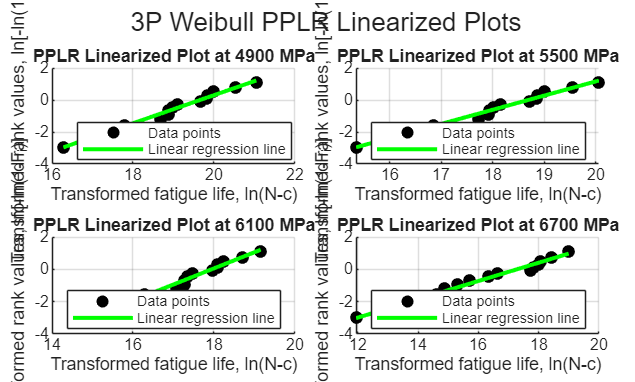

figure('Name','3P Weibull PPLR Linearized Plots');
tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

for j = 1:num_stress_levels
    nexttile
    scatter(probability_X{j}, probability_Y{j}, 40, 'k', 'filled');
    hold on;
    plot(probability_X{j}, probability_Y_fit{j}, 'g-', 'LineWidth', 2);
    xlabel('Transformed fatigue life, ln(N-c)');
    ylabel('Transformed rank values, ln[-ln(1-F_i)]');
    title(sprintf('PPLR Linearized Plot at %g MPa', stress_levels(j)));
    legend('Data points','Linear regression line','Location','best');
    grid on;
    hold off;
end
sgtitle('3P Weibull PPLR Linearized Plots');

## Goodness-of-Fit test and Tail-fit effect check 

This part of the code was written with the aid of ChatGPT (the in-built matlab function for adtest does not work on the 3P Weibull). 

% Anderson-Darling statistic with parametric bootstrap calibration
% The PPLR method is repeated for each bootstrap sample.

rng(1); % Reproducible bootstrap results

num_bootstrap = 999;
num_c_grid = 1000; % Grid points used during bootstrap refitting
alpha = 0.05;

AD_statistic_3PW = zeros(num_stress_levels,1);
AD_p_value_3PW = zeros(num_stress_levels,1);

for j = 1:num_stress_levels
    current_stress = stress_levels(j);
    life_j = data.NumberOfCycles(data.ContactStressAmplitude_MPa_ == current_stress);
    life_j = sort(life_j(:));
    n = numel(life_j);

    % PPLR estimates obtained in Section 2.2
    a_hat = a_estimates(j);
    b_hat = b_estimates(j);
    c_hat = c_estimates(j);

    % Calculate the observed AD statistic
    F_obs = (life_j > c_hat) .* (1 - exp(-((life_j - c_hat) ./ a_hat).^b_hat));
    F_obs = min(max(F_obs, eps), 1-eps);
    i = (1:n)';
    AD_obs = -n - sum((2*i-1) .* (log(F_obs) + log(1 - flipud(F_obs)))) / n;
    AD_statistic_3PW(j) = AD_obs;
    % Parametric bootstrap under the fitted 3P Weibull model
    AD_bootstrap = NaN(num_bootstrap,1);

    for k = 1:num_bootstrap
        % Generate a sample from the fitted 3P Weibull distribution
        U = rand(n,1);
        life_boot = c_hat + a_hat .* (-log(1-U)).^(1/b_hat);
        life_boot = sort(life_boot);
        % Re-estimate the 3P Weibull parameters using PPLR
        [a_boot, b_boot, c_boot] = fit3PW_PPLR(life_boot, num_c_grid);

        if ~isfinite(a_boot) || ~isfinite(b_boot) || ~isfinite(c_boot) || a_boot <= 0 || b_boot <= 0
            continue
        end

        % Calculate the AD statistic for the refitted sample
        F_boot = (life_boot > c_boot) .* (1 - exp(-((life_boot - c_boot) ./ a_boot).^b_boot));
        F_boot = min(max(F_boot, eps), 1-eps);
        AD_bootstrap(k) = -n - sum((2*i-1) .* (log(F_boot) + log(1 - flipud(F_boot)))) / n;
    end
    AD_bootstrap = AD_bootstrap(isfinite(AD_bootstrap));
    % Bootstrap p-value
    AD_p_value_3PW(j) = ...
        (1 + sum(AD_bootstrap >= AD_obs)) / ...
        (1 + numel(AD_bootstrap));

end

% Display results
AD_results_3PW = table(stress_levels, AD_statistic_3PW,AD_p_value_3PW, AD_p_value_3PW >= alpha,'VariableNames', {'Stress_MPa','AD_Statistic', ...
    'Bootstrap_p_value','FailToRejectAt5Percent'});

AD_results_3PW

AD_results_3PW = 4×4 table
    Stress_MPa    AD_Statistic    Bootstrap_p_value    FailToRejectAt5Percent
    __________    ____________    _________________    ______________________

       4900         0.22754             0.656                  true          
       5500          0.2266             0.657                  true          
       6100         0.22669             0.669                  true          
       6700          0.2482             0.566                  true          


## Export Results 

% Save results and plotting data for the combined plotting script - This
% section was written with assistance from ChatGPT
save('results_3PW_Steel.mat', ...
    'stress_levels', ...
    ... % MLE estimates
    'a_estimates_MLE', ...
    'b_estimates_MLE', ...
    'c_estimates_MLE', ...
    'B1_lives_3PW_MLE', ...
    'MLE_results_3PW', ...
    'min_life', ...
    'location_gap', ...
    'location_check', ...
    'a_estimates', ...
    'b_estimates', ...
    'c_estimates', ...
    'B1_lives_3PW_PPLR', ...
    'max_r_array', ...
    'PPLR_results_3PW', ...
    'cdf_x', ...
    'cdf_3PW_PPLR', ...
    'cdf_life_sorted', ...
    'cdf_empirical_F', ...
    'probability_X', ...
    'probability_Y', ...
    'probability_Y_fit', ...
    'AD_statistic_3PW', ...
    'AD_p_value_3PW', ...
    'AD_results_3PW', ...
    'num_bootstrap', ...
    'num_c_grid', ...
    'alpha', ...
    'tail_fit_lives_3PW', ...
    'tail_fit_F_empirical_3PW', ...
    'tail_fit_dF_3PW', ...
    'tail_fit_abs_dF_3PW')

% function used in parametric boostrap approach for estimating ad statistics 
function [a_hat, b_hat, c_hat] = fit3PW_PPLR(life, num_c_grid)
    life = sort(life(:));
    n = numel(life);
    % Median rank plotting positions
    ranks = (1:n)';
    F = (ranks - 0.3) ./ (n + 0.4);
    Y = log(-log(1-F));

    % Search for the location parameter
    c_range = linspace(0, 0.999*min(life), num_c_grid);
    max_r = -Inf;
    c_hat = NaN;
    X_best = [];
    for q = 1:numel(c_range)
        X = log(life - c_range(q));
        R = corrcoef(X,Y);
        r = R(1,2);

        if isfinite(r) && r > max_r
            max_r = r;
            c_hat = c_range(q);
            X_best = X;
        end
    end
    if isempty(X_best)
        a_hat = NaN;
        b_hat = NaN;
        c_hat = NaN;
        return
    end
    % Linear regression
    coeff = polyfit(X_best,Y,1);
    b_hat = coeff(1);
    if b_hat <= 0
        a_hat = NaN;
        return
    end
    a_hat = exp(-coeff(2)/b_hat);
end